# 交互教学 03：含充放电互斥约束的配电网储能日前优化调度

辐射状配电网采用支路潮流模型和二阶锥松弛，储能增加充放电二进制变量。完整模型为混合整数二阶锥规划（MISOCP）。光伏装机为每节点 1.2 MW，储能为每节点 1.5 MW/3 MWh，荷电状态范围为 0.20 至 0.80。

## 使用方法

先将 MATLAB 当前文件夹切换到 interactive。首次点击“全部运行”。修改计算参数后重新运行；查看时段、支路或节点的滑块只更新所在节的图形。

lesson = ess_live_setup();
export_figures = true;

## 个人学号与本次计算条件

修改学号后重新运行后续各节。算例、负荷系数和候选节点沿用课程统一规则。

Stu_ID = 242400021;
XY=mod(Stu_ID,100);
X_digit=floor(XY/10); Y_digit=mod(XY,10);
alpha=1+0.002*XY;
if ismember(Y_digit,[0 1 2 3])
    case_name='case_nongcun';
elseif ismember(Y_digit,[4 5 6])
    case_name='case_chengshi_A';
else
    case_name='case_kaifaqu_A';
end
if ismember(X_digit,[0 1 2])
    study_buses=[4 9 14]; model_type='A';
elseif ismember(X_digit,[3 4 5])
    study_buses=[5 11 16]; model_type='B';
else
    study_buses=[6 13 17]; model_type='C';
end
profiles=load(fullfile(lesson.cases,'profiles_24h.mat'));
T=profiles.T; dt=1;
load_curve_pu=profiles.load_curve_pu; pv_curve_pu=profiles.pv_curve_pu;
price_MWh=profiles.price_MWh; price_kWh=profiles.price_kWh;
disp(table(Stu_ID,string(case_name),alpha,string(model_type),string(mat2str(study_buses)),...
    'VariableNames',{'StudentID','Case','LoadMultiplier','AssignedObjective','StudyNodes'}));

    StudentID         Case         LoadMultiplier    AssignedObjective    StudyNodes
    _________    ______________    ______________    _________________    __________

    2.424e+08    "case_nongcun"        1.042                "A"           "[4 9 14]"



mpc=loadcase(case_name);
ess_buses=study_buses;pv_buses=ess_buses;
yalmip('clear');

## 选择调度目标

默认目标按学号分配。课堂比较时，保持算例、负荷和设备参数不变，只选择目标：1 为提高光伏消纳，2 为降低网损，3 为降低购电费用。

override_objective = true;
objective_number = 3;
objective_names='ABC';
if override_objective
 model_type=objective_names(objective_number);
else
 default_objective=1+(X_digit>=3)+(X_digit>=6);
 model_type=objective_names(default_objective);
end
disp(table(string(model_type),'VariableNames',{'SelectedObjective'}));

    SelectedObjective
    _________________

           "C"       



## 读取网络及储能参数

网络功率使用标幺值。充放电功率和储能能量容量采用相同功率基准换算，时间步长为 1 小时。

Sbase = mpc.baseMVA;
N_bus = size(mpc.bus, 1);
N_br  = size(mpc.branch, 1);
N_ess = length(ess_buses);
N_pv  = length(pv_buses);
fbus = mpc.branch(:, 1); % 支路首端（上游节点）编号
tbus = mpc.branch(:, 2); % 支路末端（下游节点）编号
r_br = mpc.branch(:, 3);
x_br = mpc.branch(:, 4);
Pd_pu       = (mpc.bus(:, 3) * alpha / Sbase) * load_curve_pu';
Qd_pu       = (mpc.bus(:, 4) * alpha / Sbase) * load_curve_pu';
P_pv_max_pu = (1.2 / Sbase) * repmat(pv_curve_pu', N_pv, 1);
P_ess_rated_pu = 1.5 / Sbase;
E_ess_rated_pu = 3.0 / Sbase;
eta_ch  = 0.90;
eta_dis = 0.95;
SoC_min = 0.20;
SoC_max = 0.80;
SoC_0   = 0.50;

## 声明连续变量与充放电状态

u_ch 为每个储能、每个时段的 0-1 变量。其余网络和设备运行量保持连续。

U_bus  = sdpvar(N_bus, T, 'full'); % 节点电压幅值平方 U_{i,t} (p.u.^2)
L_br   = sdpvar(N_br,  T, 'full'); % 支路电流幅值平方 L_{ij,t} (p.u.^2)
P_br   = sdpvar(N_br,  T, 'full'); % 支路首端有功功率 P_{ij,t} (p.u.)
Q_br   = sdpvar(N_br,  T, 'full'); % 支路首端无功功率 Q_{ij,t} (p.u.)
P_grid = sdpvar(1,     T, 'full'); % 向上级电网购电有功功率 P_{grid,t} (p.u.)
Q_grid = sdpvar(1,     T, 'full'); % 上级电网注入无功功率 Q_{grid,t} (p.u.)
P_ch   = sdpvar(N_ess, T, 'full'); % 储能充电有功功率 P_{i,t}^{ch} (p.u.)
P_dis  = sdpvar(N_ess, T, 'full'); % 储能放电有功功率 P_{i,t}^{dis} (p.u.)
SoC    = sdpvar(N_ess, T, 'full'); % 储能荷电状态数组 SoC_{i,t} (N_ess x T)
P_pv   = sdpvar(N_pv,  T, 'full'); % 光伏实际出力 P_{j,t}^{pv} (p.u.)
u_ch=binvar(N_ess,T,'full');

## 充放电互斥约束

u_ch=1 时允许充电，u_ch=0 时允许放电；两种状态下均可空闲。三个目标采用相同的互斥约束。


$$0\le P_{i,t}^{\mathrm{ch}}\le u_{i,t}P_i^{\mathrm{rated}}$$


## 放电功率约束

充放电状态必须由优化模型联合决定。


$$0\le P_{i,t}^{\mathrm{dis}}\le(1-u_{i,t})P_i^{\mathrm{rated}}$$


## 节点功率平衡

上游支路送入功率减去损耗和下游支路功率，等于节点净需求。


$$P_{ij,t}-r_{ij}L_{ij,t}-\sum_kP_{jk,t}=P_{j,t}^{\mathrm{load}}-P_{j,t}^{\mathrm{pv}}+P_{j,t}^{\mathrm{ch}}-P_{j,t}^{\mathrm{dis}}$$


## 支路电压与二阶锥约束

保留支路有功、无功损耗和支路电流幅值平方。二阶锥松弛间隙需要在求解后计算。


$$P_{ij,t}^2+Q_{ij,t}^2\le U_{i,t}L_{ij,t}$$


Constraints = [];
Constraints = [Constraints, 0 <= P_ch  <= P_ess_rated_pu*u_ch];
Constraints = [Constraints, 0 <= P_dis <= P_ess_rated_pu*(1-u_ch)];
Constraints = [Constraints, SoC_min <= SoC <= SoC_max];
Constraints = [Constraints, SoC(:, T) == SoC_0];
Constraints = [Constraints, 0 <= P_pv <= P_pv_max_pu];
for t = 1:T
    if t == 1
        soc_prev = repmat(SoC_0, N_ess, 1);
    else
        soc_prev = SoC(:, t - 1);
    end
    Constraints = [Constraints, SoC(:, t) == soc_prev + ...
        (eta_ch * P_ch(:, t) - P_dis(:, t) / eta_dis) / E_ess_rated_pu];
end
A_from  = sparse(fbus, 1:N_br, 1, N_bus, N_br); % 支路首端（上游节点）关联矩阵
A_to    = sparse(tbus, 1:N_br, 1, N_bus, N_br); % 支路末端（下游节点）关联矩阵
A_ess   = sparse(ess_buses, 1:N_ess, 1, N_bus, N_ess);
A_pv    = sparse(pv_buses,  1:N_pv,  1, N_bus, N_pv);
A_slack = sparse(1, 1, 1, N_bus, 1);
P_loss_br = diag(r_br) * L_br;
Q_loss_br = diag(x_br) * L_br;
Constraints = [Constraints, A_to * (P_br - P_loss_br) - A_from * P_br + ...
    A_slack * P_grid + A_pv * P_pv + A_ess * (P_dis - P_ch) == Pd_pu];
Constraints = [Constraints, A_to * (Q_br - Q_loss_br) - A_from * Q_br + ...
    A_slack * Q_grid == Qd_pu];
Constraints = [Constraints, U_bus(1, :) == 1.0];
Constraints = [Constraints, (0.95^2) <= U_bus(2:end, :) <= (1.05^2)];
Constraints = [Constraints, L_br >= 0];
for b = 1:N_br
    i = fbus(b);
    j = tbus(b);
    Constraints = [Constraints, U_bus(j, :) == U_bus(i, :) - ...
        2 * (r_br(b) * P_br(b, :) + x_br(b) * Q_br(b, :)) + ...
        (r_br(b)^2 + x_br(b)^2) * L_br(b, :)];
    for t = 1:T
        Constraints = [Constraints, cone([2 * P_br(b, t); 2 * Q_br(b, t); ...
            L_br(b, t) - U_bus(i, t)], L_br(b, t) + U_bus(i, t))];
    end
end

## 构造目标函数并求解

本项目默认使用 MATLAB 内置求解器。任务三同时含整数变量和二阶锥约束，现有直接求解接口需要 MOSEK 或 Gurobi。任务二和任务四仍采用 linprog/intlinprog。模型 A 的网损权重保持 0.01。

Total_Loss_MWh    = Sbase * sum(sum(P_loss_br));
Total_Curtail_MWh = Sbase * sum(sum(P_pv_max_pu - P_pv));
Total_Cost_Yuan   = sum((Sbase * P_grid') .* price_MWh);
if strcmp(model_type, 'A')
    Objective = Total_Curtail_MWh + 1e-2 * Total_Loss_MWh;
elseif strcmp(model_type, 'B')
    Objective = Total_Loss_MWh + 1e-4 * sum(sum(P_ch + P_dis));
else
    Objective = Total_Cost_Yuan;
end
[sol,solver_name,solve_seconds]=ess_live_solve(Constraints,Objective,'MISOCP');

## 检查运行约束与交流潮流

三个目标均检查充放电互斥、荷电状态、功率边界和能量平衡。将相同出力代入交流潮流。目标 C 保留为二阶锥松弛不精确的教学特例，继续展示松弛间隙及交流电压偏差。

gap_matrix=abs(value(L_br).*value(U_bus(fbus,:))-value(P_br).^2-value(Q_br).^2);
socp_gap=max(gap_matrix(:));
Dispatch_Data=struct('mpc',mpc,'Stu_ID',Stu_ID,'case_name',case_name,...
    'model_type',model_type,'solver',solver_name,'solve_seconds',solve_seconds,...
    'Sbase',Sbase,'dt',dt,'ess_buses',ess_buses,'pv_buses',pv_buses,...
    'PratedMW',P_ess_rated_pu*Sbase,'EratedMWh',E_ess_rated_pu*Sbase,...
    'SoC0',SoC_0,'SoCmin',SoC_min,'SoCmax',SoC_max,...
    'eta_ch',eta_ch,'eta_dis',eta_dis,'price_MWh',price_MWh,...
    'PloadMW',Pd_pu*Sbase,'QloadMvar',Qd_pu*Sbase,...
    'PpvMW',Sbase*value(P_pv),'PpvMaxMW',P_pv_max_pu*Sbase,...
    'PchMW',Sbase*value(P_ch),'PdisMW',Sbase*value(P_dis),...
    'SoC',value(SoC),'u',value(u_ch),'U',value(U_bus),...
    'L',value(L_br),'P',value(P_br),'Q',value(Q_br),...
    'Pgrid',value(P_grid),'Qgrid',value(Q_grid));
[Dispatch_Check,V_dispatch_ac]=ess_live_check_dispatch(Dispatch_Data);
max_simultaneous_MW=Dispatch_Check.MaxSimultaneousPower_MW;
disp(Dispatch_Check);

                   ModelType: 'MISOCP'
                      Solver: 'mosek'
                   StudentID: 242400021
                        Case: 'case_nongcun'
                   Objective: 'C'
                SolveSeconds: 265.2444
     MaxSimultaneousPower_MW: 0
                      MinSoC: 0.2000
                      MaxSoC: 0.8000
            TerminalSoCError: 0
      EnergyBalanceError_MWh: 2.4009e-11
      PowerLimitViolation_MW: 1.8686e-09
         PVLimitViolation_MW: 1.5534e-09
                IntegerError: 9.7460e-10
                  MaxConeGap: 0.0020
       ActiveBalanceError_pu: 4.1925e-11
     ReactiveBalanceError_pu: 4.0533e-11
     VoltageEquationError_pu: 3.0563e-10
             MinModelVoltage: 0.9500
             MaxModelVoltage: 1.0500
             Curtailment_MWh: -5.7655e-08
                LineLoss_MWh: 1.8278
               GridCost_Yuan: 3.0412e+04
                 ACConverged: 1
                MinACVoltage: 0.9500
                MaxACVoltage: 1.0611
   

assert(Dispatch_Check.StorageConstraintsPassed && Dispatch_Check.LinearConstraintsPassed,...
    '本次结果的储能或线性约束偏差超出要求，请查看 Dispatch_Check。');
if Dispatch_Check.TeachingCounterexample
    disp('目标 C 教学特例：二阶锥松弛不精确。请比较模型电压与交流潮流电压，并分析松弛间隙和交流电压越限。');
else
    assert(Dispatch_Check.Passed,'请检查二阶锥松弛间隙与交流电压。');
end

目标 C 教学特例：二阶锥松弛不精确。请比较模型电压与交流潮流电压，并分析松弛间隙和交流电压越限。


Dispatch_Result=table(Stu_ID,string(case_name),string(model_type),string(solver_name),...
    Dispatch_Check.Curtailment_MWh,Dispatch_Check.LineLoss_MWh,...
    Dispatch_Check.GridCost_Yuan,socp_gap,max_simultaneous_MW,...
    Dispatch_Check.MinACVoltage,Dispatch_Check.MaxACVoltage,...
    'VariableNames',{'StudentID','Case','Objective','Solver','Curtailment_MWh',...
    'Loss_MWh','GridCost_Yuan','MaxConeGap','SimultaneousPower_MW','MinACVoltage','MaxACVoltage'});
disp(Dispatch_Result);

    StudentID         Case         Objective    Solver     Curtailment_MWh    Loss_MWh    GridCost_Yuan    MaxConeGap    SimultaneousPower_MW    MinACVoltage    MaxACVoltage
    _________    ______________    _________    _______    _______________    ________    _____________    __________    ____________________    ____________    ____________

    2.424e+08    "case_nongcun"       "C"       "mosek"      -5.7655e-08       1.8278         30412        0.0020468              0                  0.95           1.0611   



if ~exist('Dispatch_History','var') || ~istable(Dispatch_History) ||...
        ~isequal(Dispatch_History.Properties.VariableNames,Dispatch_Result.Properties.VariableNames)
    Dispatch_History=Dispatch_Result;
else
    Dispatch_History=[Dispatch_History;Dispatch_Result];
end
disp(Dispatch_History);

    StudentID         Case         Objective    Solver     Curtailment_MWh    Loss_MWh    GridCost_Yuan    MaxConeGap    SimultaneousPower_MW    MinACVoltage    MaxACVoltage
    _________    ______________    _________    _______    _______________    ________    _____________    __________    ____________________    ____________    ____________

    2.424e+08    "case_nongcun"       "A"       "mosek"      -3.0454e-08      0.95095         32658        2.2083e-10             0                0.97251          1.0428   
    2.424e+08    "case_nongcun"       "B"       "mosek"            9.838      0.62428         39782        4.7933e-10             0                0.97251               1   
    2.424e+08    "case_nongcun"       "C"       "mosek"      -5.7655e-08       1.8278         30412         0.0020468             0                   0.95          1.0611   



## 查看储能充放电功率与荷电状态

选择一个储能节点，同时显示充电功率与放电功率。电价和荷电状态使用独立坐标轴。

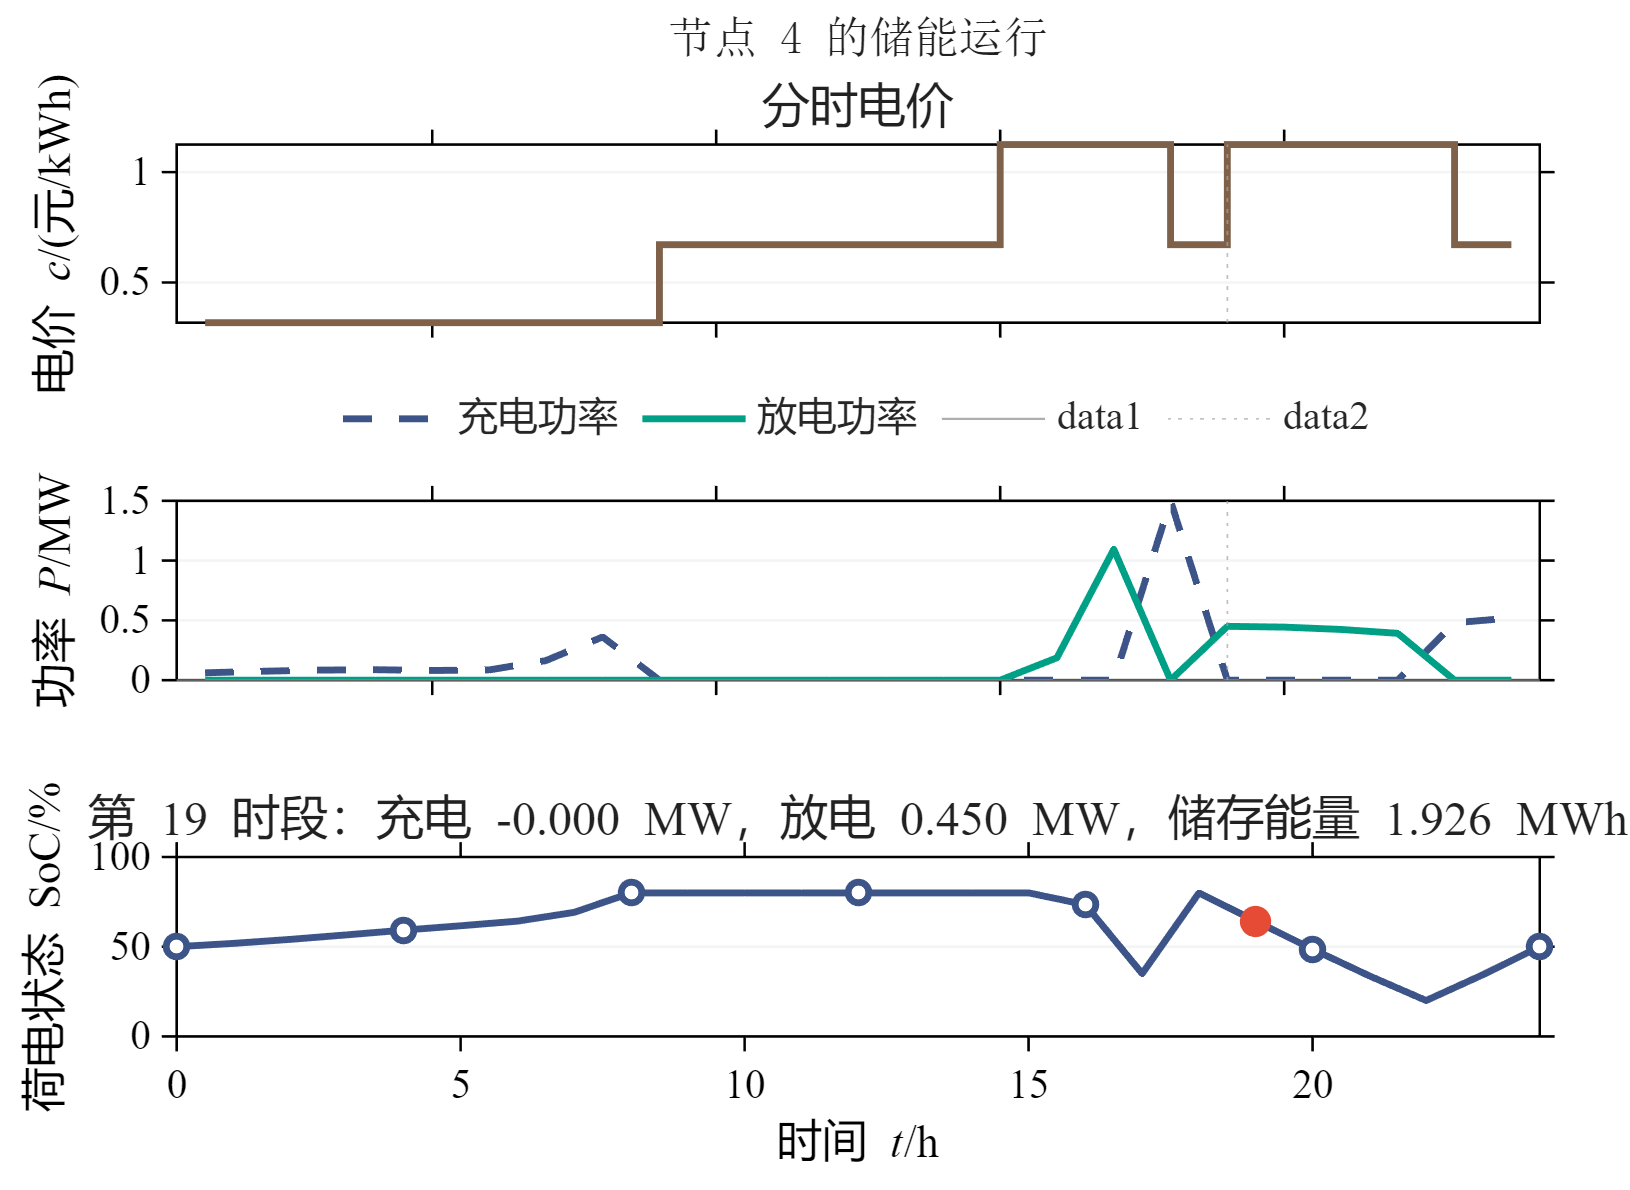

view_storage = 1;
fig_dispatch_storage=ess_live_view('dispatch_storage',price_kWh,Dispatch_Data.PchMW(view_storage,:)',Dispatch_Data.PdisMW(view_storage,:)',Dispatch_Data.SoC(view_storage,:)',19,1,Dispatch_Data.EratedMWh);
sgtitle(sprintf('节点 %d 的储能运行',ess_buses(view_storage)),'FontName','宋体');

## 查看交流节点电压与二阶锥松弛间隙

节点电压图使用交流潮流计算结果。时段滑块只更新图形。电压上下限保留在模型和检查结果中，图中默认不画限值线。

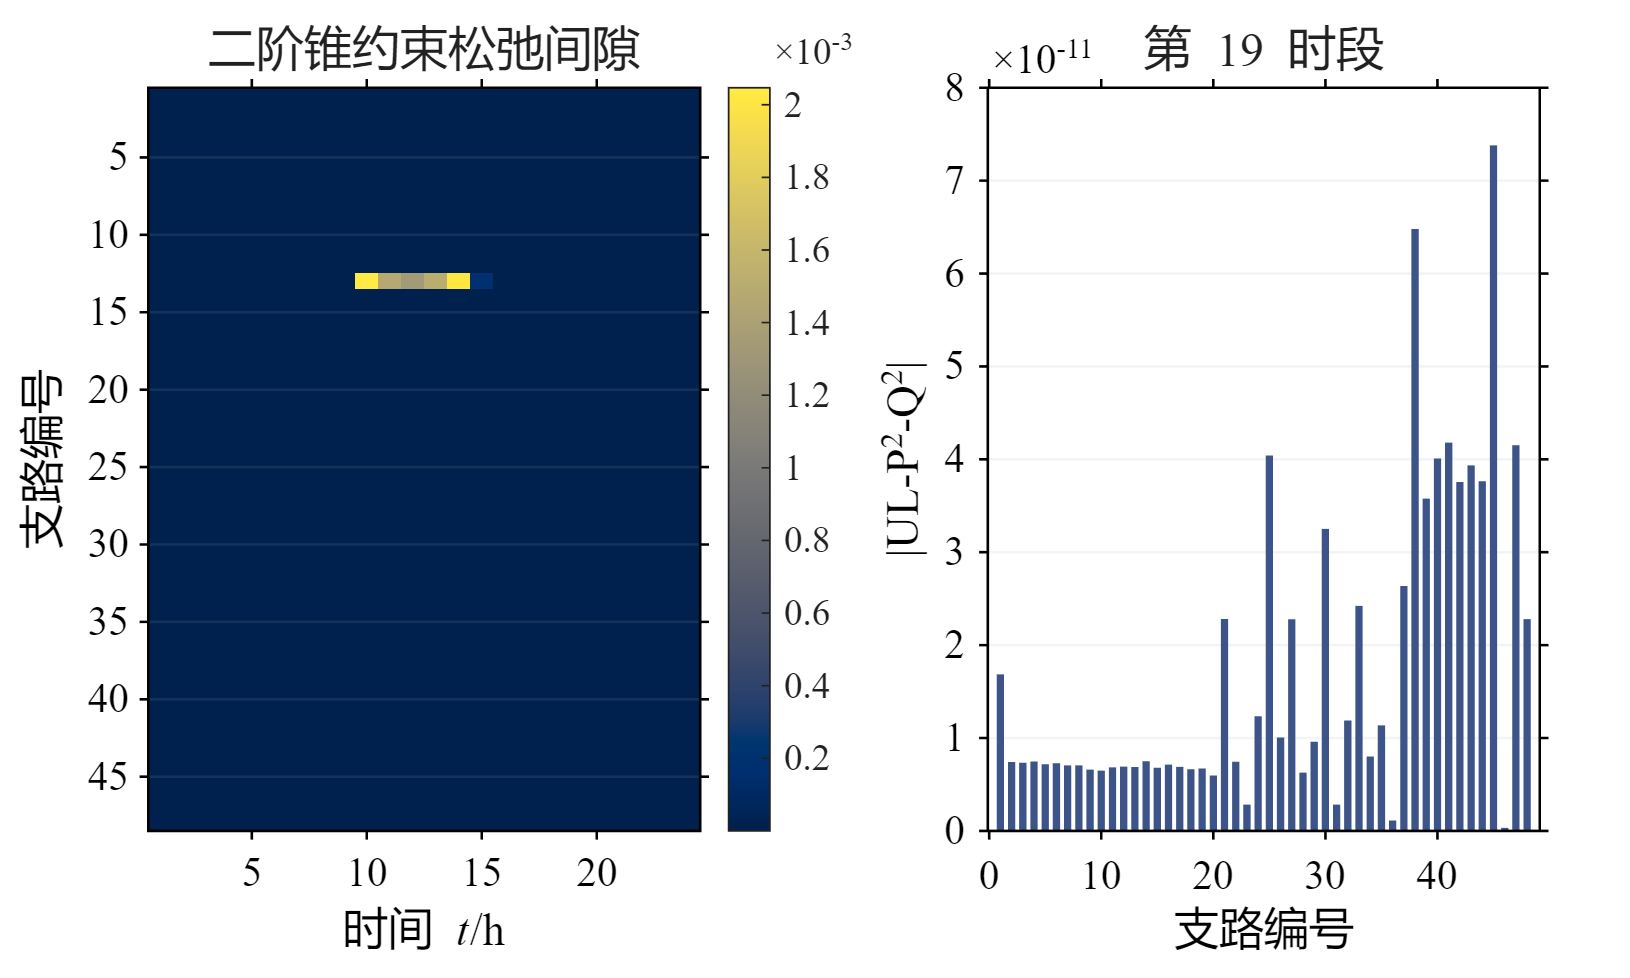

view_hour = 19;
fig_gap=ess_live_view('gap',gap_matrix,view_hour);

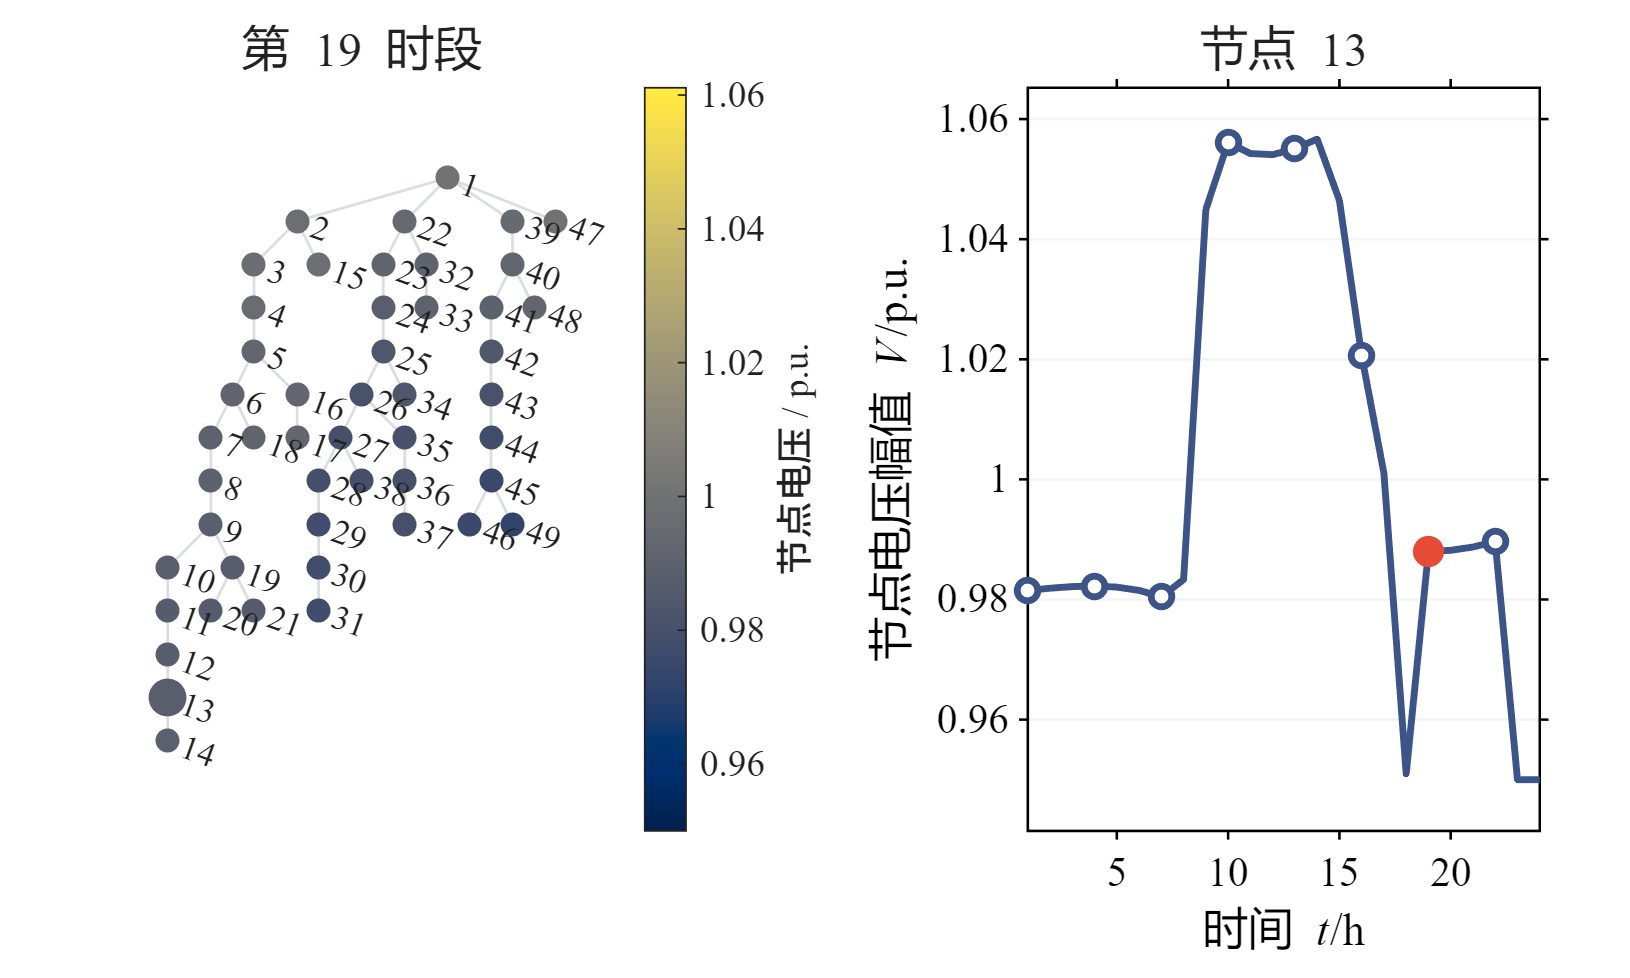

V_socp=sqrt(Dispatch_Data.U);
fig_dispatch_voltage=ess_live_view('voltage',mpc,V_dispatch_ac,view_hour,13);

## 比较二阶锥模型与交流潮流电压

目标 C 中，请找出两种计算电压偏差最大的节点，解释模型电压满足约束而交流电压仍可能越限的原因。图中默认不画电压限值线，完整限值见参数和检查结果。

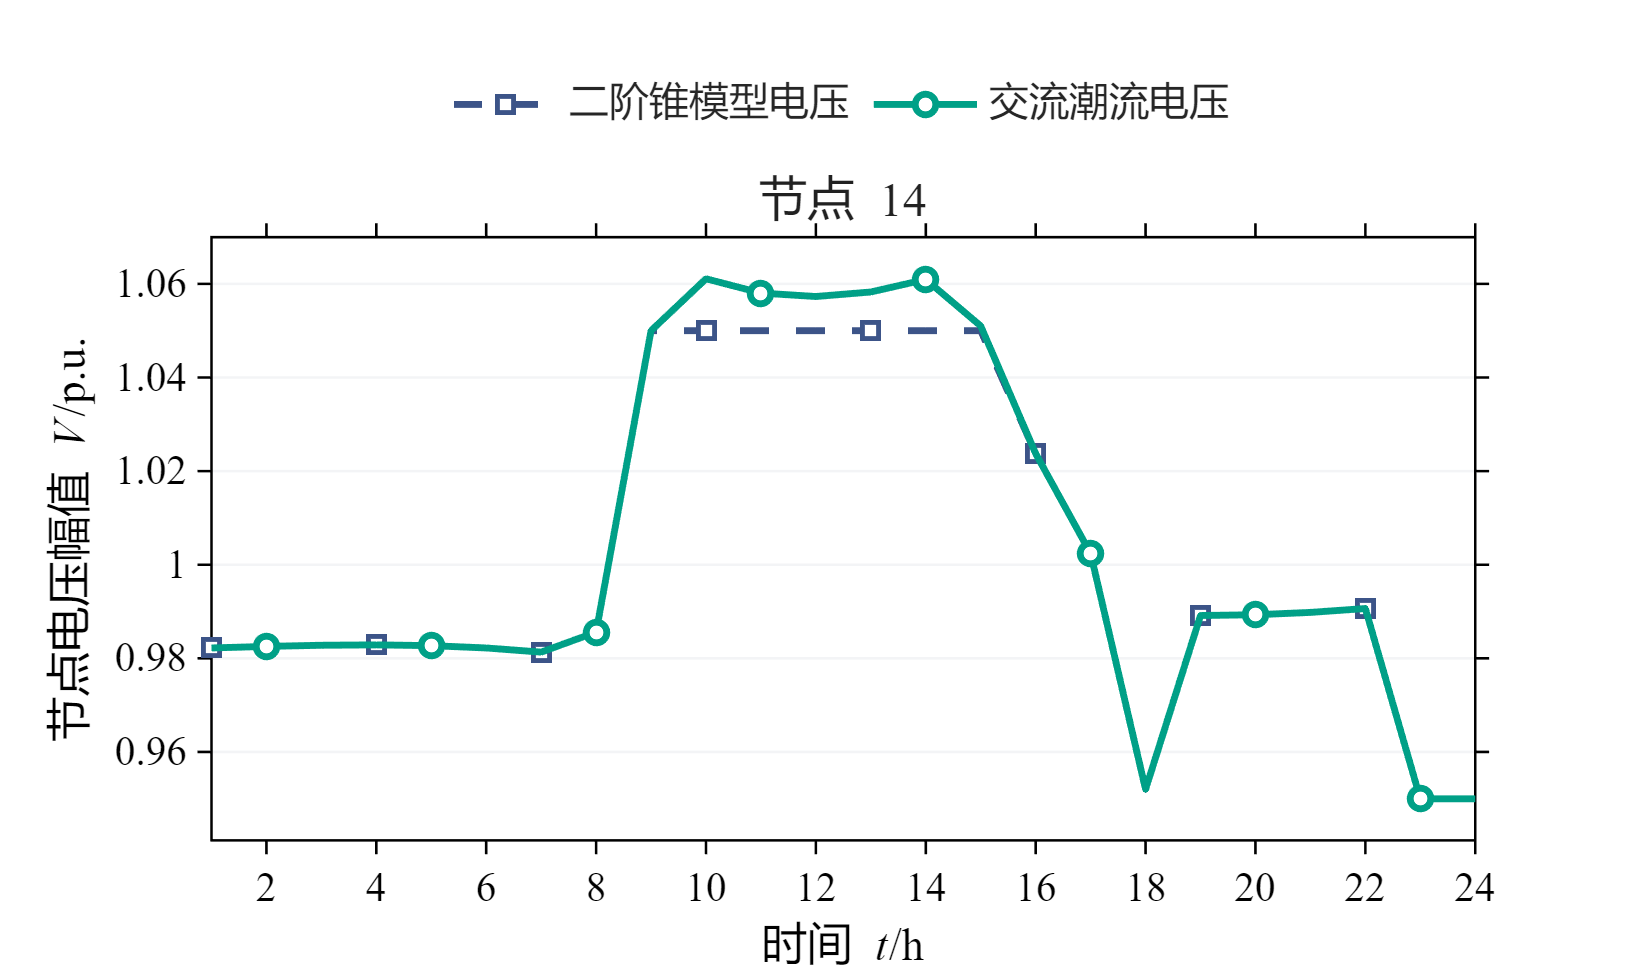

view_voltage_node = 0;
if view_voltage_node==0,compare_node=Dispatch_Check.MaxVoltageErrorNode;else,compare_node=min(view_voltage_node,N_bus);end
fig_dispatch_compare=ess_live_view('relaxation_voltage',V_socp,V_dispatch_ac,compare_node);

## 关联矩阵与支路的对应关系

选中一条支路，查看其在首末端关联矩阵中的位置。

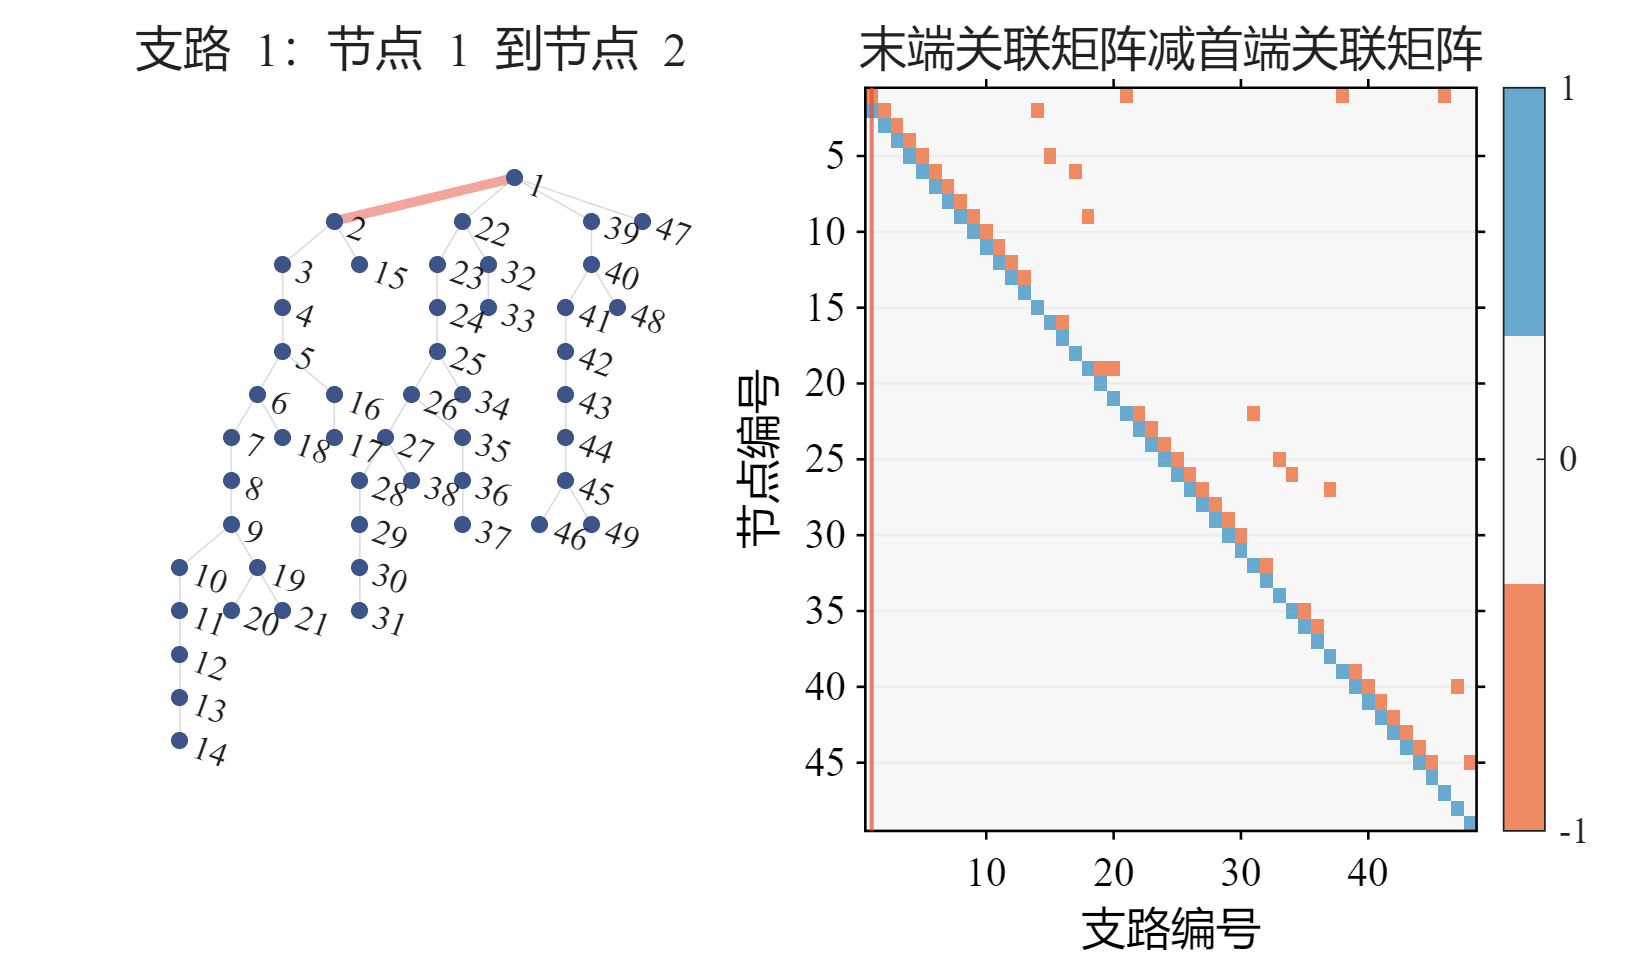

view_branch = 1;
view_branch=min(view_branch,N_br);
fig_matrix=ess_live_view('matrix',mpc,view_branch);

## 保存结果与目标比较练习

保持同一算例和设备参数，分别计算 A/B/C。比较弃光电量、交流电能损耗、购电费用、荷电状态和节点电压。

out_dir=fullfile(lesson.results,sprintf('Lesson03_%d_%s',Stu_ID,model_type));
if ~isfolder(out_dir),mkdir(out_dir);end
save(fullfile(out_dir,'dispatch_result.mat'),'Dispatch_Data','Dispatch_Check','V_dispatch_ac','Dispatch_Result');
if export_figures
 ess_live_export(fig_gap,out_dir,'Cone_Gap');
 ess_live_export(fig_dispatch_storage,out_dir,'Storage_Operation');
 ess_live_export(fig_dispatch_voltage,out_dir,'Dispatch_Voltage');
 ess_live_export(fig_dispatch_compare,out_dir,'Relaxation_Voltage_Comparison');
 ess_live_export(fig_matrix,out_dir,'Network_Matrix');
end

Lesson_Stats=Dispatch_Check;